# Tipos de datos

**Ideas previas:**

Indistintamente de que se cree un escalar, un vector o una matriz, MATLAB creará arreglos bidimensionales para cada caso.

clear

A = 1;
B = 1:5;
C = [1 2; 3 4];

whos    % O se puede ver en el área de trabajo también.

Además, por defecto MATLAB asignará el tipo de dato numérico `double` (doble) a las variables numéricas creadas. Sin embargo, a continuación se estudiará qué otros tipos de datos existen y cuál es su utilidad.

El tipo de datos (también llamado clase) principal en MATLAB es el arreglo o matriz. Dentro del arreglo, MATLAB soporta algunos tipos diferentes de datos secundarios.

En general, todos los datos dentro de un arreglo deben ser del mismo tipo. Sin embargo, MATLAB también incluye funciones para convertir entre tipos de datos y tipos de arreglos, para almacenar diferentes tipos de datos en el mismo arreglo (arreglos celda y estructura).

A continuación, se muestran los tipos de datos que se puede almacenar en MATLAB:

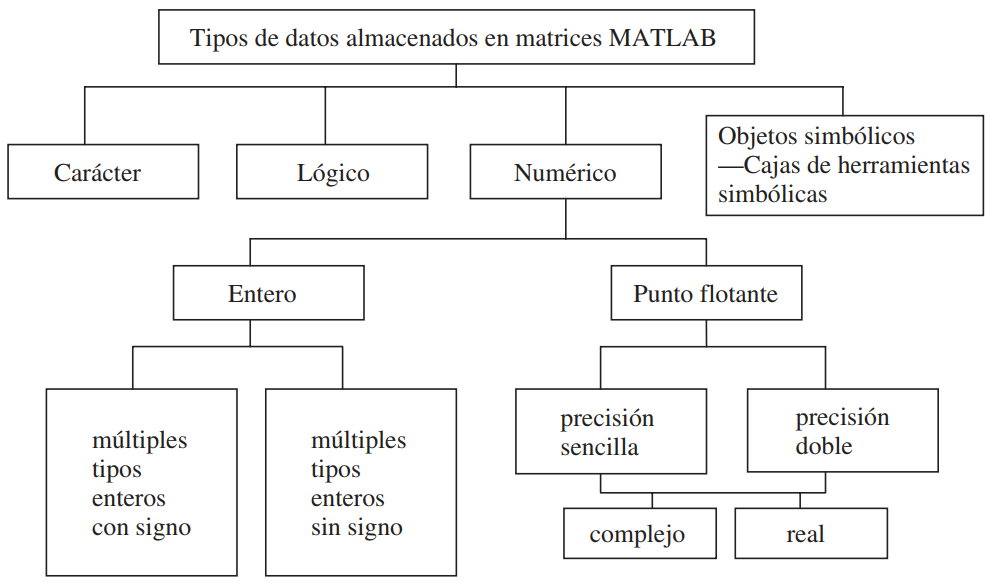

A su vez, también se muestran los tipos de arreglos que se pueden obtener con MATLAB:

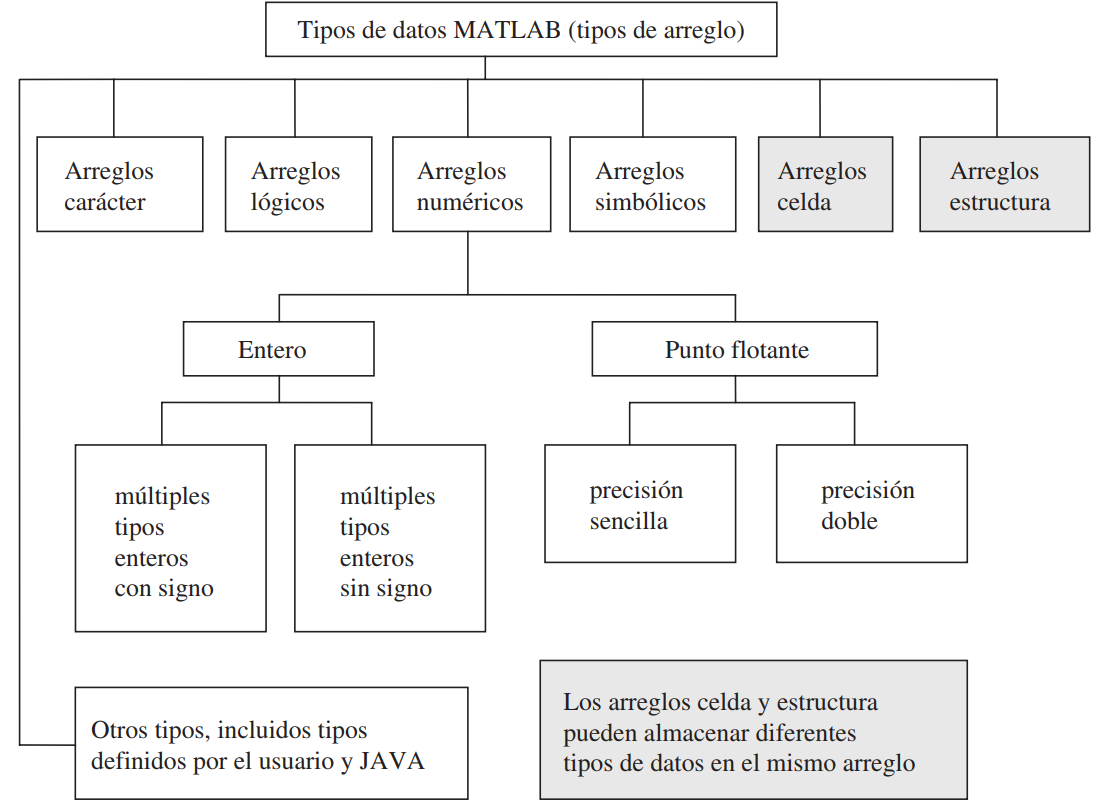

**Nota:** Un detalle importante es que sin importar el tipo de dato que se asigne a una variable, ésta siempre será un arreglo en MATLAB.

## Datos numéricos

### Números punto flotante de precisión doble

Tipo de dato numérico por defecto en MATLAB. Este tipo de números son los denominados `double` (aunque en otros lenguajes se los conoce como `float` de doble precisión) y sus características son las siguientes:

- Es el tipo dato numérico más grande del que se dispone en MATLAB.

- Muy recomendado para evitar problemas de redondeo.

- Cada `double` ocupa 8 bytes (64 bits) de almacenamiento. Por ejemplo, si un arreglo contiene 4 `double`, ese arreglo tendrá un tamaño de 32 bytes.

- Para conocer el `double` más grande que puede almacenar MATLAB se puede utilizar la función `realmax`. Cualquier número por encima de `realmax` MATLAB lo interpreatará como infinito (`Inf`).

- Para conocer el `double` más pequeño que puede almacenar MATLAB se puede utilizar la función `realmin`. Cualquier número por debajo de `realmin` MATLAB lo interpreatará como cero.

realmax     % Double máximo.
1e350       % Número más grande que el double máximo.

realmin     % Double mínimo.
1e-350      % Número más pequeño que el double mínimo.

**Nota:** Un detalle importante es que, a excepción de este tipo de dato numérico, todos los tipos de datos numéricos se deben especificar. Es decir, si no se quiere utilizar un `double` y se quiere utilizar un `single`, por ejemplo, se debe especificar.

A continuación se detalla más.

### Números punto flotante de precisión sencilla

Se podría decir que este tipo de número (`single`) es el que viene detrás del `double`. Entre sus características se tiene:

- Utilizan la mitad del espacio de almacenamiento de un `double`.

- Se debe especificar que se quiere utilizar este tipo de dato mediante la función `single`.

- Como se puede intuir, al requerir menos espacio también almacena menos información.

- Para conocer el `single` máximo se utiliza la función `realmax('single')`.

- Para conocer el `single` mínimo se utiliza la función `realmin('single')`.

- Al igual que pasaba para los `double`, si se crea un número mayor que el `realmax('single')` MATLAB interpretará el valor como `Inf`. Para un número menor al `realmin('single')` la interpretación será cero.

clear

A = single(5.90);       % Creación de un single.
B = double(A);          % Creación de un double.

whos

realmax('single')
realmin('single')

#### Ejemplo de `double` VS. `single` 

Quizá se esté preguntando de qué sirve tener dos tipos de números punto flotante (`float`): un `single` y un `double`. Note algo, estos números difieren en su espacio de almacenamiento (y pasará lo mismo con el resto de números que se verá a continuación).

En programación es realmente importante tener en cuenta el tamaño de las variables y no tiene mucho sentido asignar un `double` a una variable que desperdicie todo el espacio que se le está asignando. Por supuesto que no se ve la diferencia si se calculan matrices a lo sumo de dimensión `10x10`, o se hacen operaciones con ellas.¿Pero qué pasaría con matrices `1000000x1000000`? O más grandes aún. 

La programación no es para hacer cálculos pequeños. En general, su potencial está en hacer cálculos que serían absurdos para los humanos. Sin embargo, las computadoras tienen un límite y si se sabe utilizar los recursos se puede aumentar este límite.

Otro gran problema, del cual se realizará el ejemplo, es el redondeo. Si bien tener un número que requiera menor espacio (`single`) puede ser útil, éste también posee menor espacio de almacenamiento. Por ende, su límite es mucho menor que el de un `double`.

Sea la siguiente serie armónica: $\sum^{\infty}_{n=1}{\frac{1}{n}}$, realizar la suma acumulada.

clear

n1 = 1:1e7;          % Vector n con datos tipo double.
harmonic1 = 1./n1;
partial_sum1 = cumsum(harmonic1); % Suma acumulada de la serie armónica.

Para visualizar cómo es la serie armónica sería ideal graficarla, sin embargo, dada la inmensidad de elementos que tiene `n`, se seleccionará un subrango (de lo contrario MATLAB se demoraría mucho en graficar tal cantidad de puntos).

m1 = 1000:1000:1e7;
partial_sums_selected1 = partial_sum1(m1);
plot(partial_sums_selected1)

Ahora, ¿qué pasaría si realizamos lo mismo pero con números `single`?

n2 = single(1:1e7);          % Vector n con datos tipo double.
harmonic2 = 1./n2;
partial_sum2 = cumsum(harmonic2); % Suma acumulada de la serie armónica.

m2 = 1000:1000:1e7;
partial_sums_selected2 = partial_sum2(m2);
hold on
plot(partial_sums_selected2,'r')
    title 'Comparación de cálculos de presición doble y sencilla (double VS. single)'
    ylabel 'Suma de la serie armónica'
    xlabel 'Número de pasos*1000'
    legend('Double','Single','Location','best')
hold off

Como podemos evidenciar en la gráfica, los datos tipo `single` tienen un problema muy grande con el redondeo y llega a un punto donde la serie armónica toma valores tan pequeños (para el mínimo de los números `single`) que para MATLAB prácticamente es cero y se estarían sumando estos ceros.

Por otra parte, la serie armónica con los datos `double` sigue creciendo, lo que es una muestra clara que la precisión de los `double` es muy buena pues su límite es muy grande.

### Números enteros

El concepto de número entero para MATLAB (`int`), o para la programación en general, es el mismo que todos dominamos: números sin parte decimal. Ahora bien, MATLAB dispone de 8 tipos de números enteros los cuales se detallan a continuación:

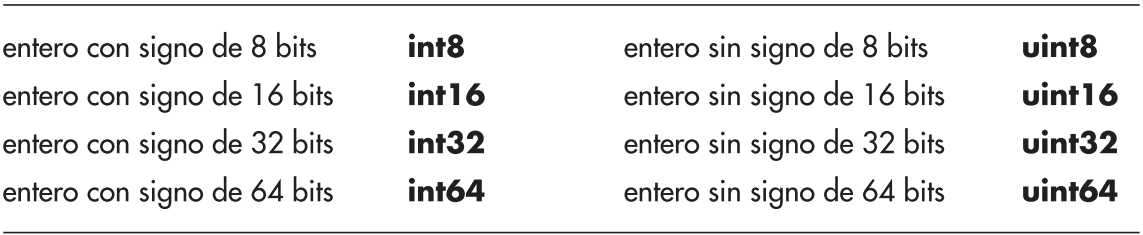

Los enteros del tipo `int` (integer) pueden ser positivos o negativos, y el espacio de almacenamiento determina cuál es su límite.

Los enteros del tipo `uint` (unsigned integer) no tienen signo, lo que técnicamente los hace positivos siempre.

Para consultar el límite de un entero (de cualquier tipo) se utiliza la función `intmax`. Por ejemplo, `intmax('int32')` devolvería el límite de los enteros de 32 bits con signo. La función `intmin` devuelve el mínimo.

Aquí puede volver la pregunta de ¿por qué tantos enteros? Pues bien, la respuesta es la misma que se dio para los `double` VS. `single`: depende del uso. Si queremos almacenar número de materias tomadas en un semestre (`numberSubjects`), ¿cuál sería la utilidad de asignar tanto espacio con un `double` (8 bytes) a una variable `numberSubjects` que a lo sumo tendrá un valor menor de 10?

Recordemos que `double` tiene el límite más grande para datos numéricos. En lugar de usar un `double`, que es el tipo de dato numérico más grande (y por ende requiere más espacio), ¿qué tal usar un tipo de dato `int8` que requiere 8 bits (1 byte)? 

Se insiste en que parece ridículo pensar en que 7 bytes, por ejemplo, harán la diferencia. Sin embargo, una universidad tiene miles de estudiantes, ¿ahí se notará la utilidad de optimizar los recursos? La respuesta es obvia.

Otro ejemplo: la edad de una persona en un país. Es poco probable que la edad de una persona supere los 127 años (límite máximo de `int8`), ¿entonces no sería razonable utilizar un tipo de dato numéricos `int8` para optimizar procesos en lugar de un `double` o `single`? Teniendo en cuenta que un país tiene millores de ciudadanos esto sería bastante útil.

Sin embargo, quizá alguien se cuestione y piense que, aunque es poco probable, podría ser que una persona supere los 127 años. En ese caso tendríamos un problema puesto que si intenta ingresar un número mayor a 127 en un `int8` le devolverá siempre el máximo.

age = int8(128)

Pero, ¿la edad de una persona es siempre positiva, verdad? Entonces sería una mejor idea utilizar `uint8` que ocupa el mismo espacio pero el límite es mayor que el de `int8` porque `uint8` no guarda espacio para el signo. Entonces tendríamos

age = uint8(128)

Así hemos optimizado el proceso sin requerir de más espacio.

**En conclusión**, siempre dependerá de la situación el tipo de dato numérico que se escoja, siempre y cuando se trabajen con miles o cientos de miles de datos. Sin embargo, si se trabajan con pocos datos no es necesario darle muchas vueltas al asunto.

Pero no está demás haber explicado todo lo anterior.

### Números complejos

Los números complejos requieren el doble de espacio del tipo de dato numérico que se le esté asignando porque requiere espacio para la parte real y para la parte imaginaria.

Por ende, si se crea un complejo tipo `double` requeriría de 16 bytes (8 bytes por cada parte):

z1 = complex(1,2)

Si se crea un complejo tipo `int8` se requeriría de 16 bits (8 bits por cada parte):

z2 = int8(5 - 6i)

Así con cualquier tipo de dato numérico.

## Datos caracter y cadena

Un caracter básicamente es una letra, número o símbolo; y una cadena es un arreglo de caracteres.

- Cada caracter ocupa un espacio de almacenamiento de 2 bytes.

- Los caracteres o cadenas de caracteres (`char`) se ingresan entre apóstrofes.

- En cambio, una cadena (`string`) se ingresa entre comillas dobles.

clear

H = 'a'                             % Caracter.

K = 'MATLAB es muy útil.'           % Cadena de caracteres.

S = "¿Vamos a la Foch?"      % Cadena.

¿Cuál es la diferencia entre una cadena y un caracter (o una cadena de caracteres)? Pues bien, una cadena (`string`) ocupa mucho más espacio que un caracter (o una cadena de caracteres: `char`).

Pero la principal diferencia entre una cadena y un caracter (o cadena de caracteres) es que una cadena no es iterable, mientras que un caracter (o cadena de caracteres) si lo es.

clear

a = 'Hola';     % Cadena de caracteres.
b = "Hola";     % Cadena.

for i = a       % Un caracter (o cadena de caracteres) es iterable.
   disp(i) 
end

for i = b       % Una cadena no es iterable.
    disp(i)
end

**Nota:** Los números son caracteres únicamente si se los ingresa entre apóstrofes, caso contrario MATLAB los reconoce como datos numéricos.

### Esquemas de codificación ASCII y EBCDIC

Toda la información en las computadoras se almacena como una serie de ceros y unos. Existen dos esquemas de codificación principales para hacer esto, llamados ASCII y EBCDIC.

- **ASCII:** **A**merican **S**tandard **C**ode for **I**nformation **I**nterchange.

- **EBCDIC:** **E**xtended **B**inary **C**oded **D**ecimal **I**nterchange **C**ode.

La mayoría de las computadoras pequeñas usan el esquema de codificación ASCII, mientras que muchas unidades centrales (mainframes) y supercomputadoras usan EBCDIC. Puede pensar en la serie de ceros y unos como un binario, o número de base 2. En este sentido, toda la información de computadora se almacena numéricamente. Todo número de base 2 tiene un equivalente decimal. En la tabla se muestran algunos números en cada base.

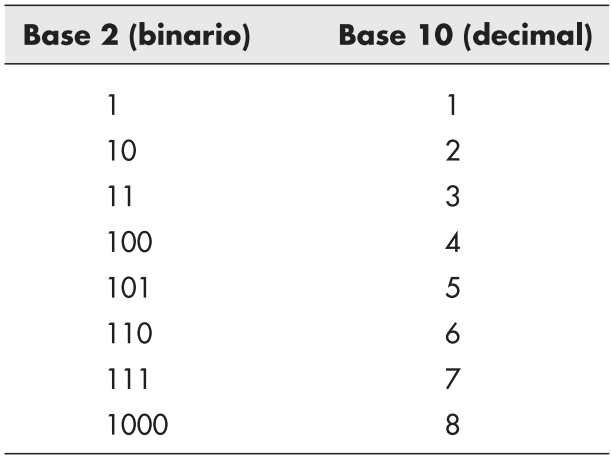

Cada carácter ASCII (o EBCDIC) almacenado tiene tanto representación binaria como equivalente decimal.

Cuando se pide a MATLAB cambiar un caracter a un `double`, el número que se obtiene es el equivalente decimal en el sistema de codificación ASCII.

double('a')

Además, así como se puede cambiar de caracter a `double`, también es posible ir en sentido contrario con la función `char`.

char(97)

**Nota:** Con una búsqueda sencilla en internet es posible encontrar la codificación ASCII y sus equivalencias decimales.

Si, por otra parte, se intenta crear una matriz que contenga tanto información numérica como información caracter, MATLAB convierte todos los datos a información caracter:

['a' 98]

Por otra parte, si se intenta realizar cálculos matemáticos con información numérica y caracter, MATLAB convierte el caracter a su equivalente decimal:  

'a' + 3

Recordemos que la representación decimal de `'a'` en el sistema de codificación ASCII es 97.

## Datos simbólicos

Los datos simbólicos básicamente son expresiones simbólicas con las que hemos trabajado toda la vida.

Para establecer datos simbólicos se utiliza la función `syms` la cual permite definir variables simbólicas.

Sea la función $f(x,y) = x^2 + y^2$, tenemos

clear

syms 'x' 'y'
f(x,y) = x^2 + y^2

Notemos que no hemos definido en ningún lugar valores para **x** y **y**, únicamente estas variables se han definido como símbolos (como hemos trabajado en cualquier ingeniería).

Para evaluar basta con dar valores a **x** y **y** (se insiste: tal cual se ha venido trabajando en cualquier ingeniería).

f(2,2)

Ojo, el resultado de `f(2,2)` también es simbólico, no es un número. Para convertir el valor de la respuesta de simbólico a numérico basta con usar alguna de las funciones de tipo de datos numéricos.

double(f(2,2))

Una vez hecha la conversión ya se puede trabajar con el valor puesto que ya es un número.

Si se intentara definir la misma expresión sin haber establecido las variables simbólicas con `syms` nos generaría un error.

clear

f(x,y) = x^2 + y^2

El error se debe a que no están definidas ni **x** ni **y** (ni como matrices ni como símbolos).

Para corregir el anterior error, sin utilizar variables simbólicas, bastaría con dar valores a **x** y **y** previamente.

clear

x = 1:10;
y = 2:2:20;

f = x.^2 + y.^2

Debemos recordar que la operación sería tipo arreglo, es decir, se escribe un punto antes de la operación. Si no se escribiera el punto MATLAB interpretaría que es una operación matricial.

En resumen, los datos simbólicos son básicamente las expresiones con las que hemos trabajado desde siempre. Pueden resultar muy útiles para visualizar funciones o evaluarlas. Únicamente se debe considerar que las evaluaciones de las funciones son también simbólicas, y para operar con ellas se debe convertir a datos numéricos.

## Datos lógicos

Los datos lógicos provienen del álgebra booleana, donde 0 representa falso (`false`) y 1 representa verdadero (`true`). También se los pueder llamar 0 lógico y 1 lógico.

Además, es posible realizar arreglos de datos lógicos:

clear

M = [true false false true]

Como se puede observar, el arreglo devuelto es lógico.

Sin embargo, en general los arreglos lógicos se crean a partir de comparaciones lógicas.

x = 1:5
y = randi([0,8],1,5)

z = x>y

En este caso, comparamos **x** y **y** para generar el arreglo lógico **z**.

**Recomendación:** En capítulos anteriores se vino desarrollando el concepto y la aplicación de estos datos, así que se recomienda revisarlos para mayor detalle si se requiere, o en su defecto se puede consultar la documentación.

## Arreglos esparcidos

Este tipo de arreglos son principalmente útiles para ahorrar espacio de almacenamiento.

En ocasiones se pueden tener matrices "escasamente pobladas", lo que significa que muchos de sus elementos son cero. Sin embargo, por defecto MATLAB reserva espacio para cada elemento sea cero o no (8 byte por elemento).

Así pues, si se tienen matrices de este tipo es mejor generar un arreglo esparcido donde MATLAB sólo recordará la posición de los elementos diferentes de cero (lo que ahorrará mucho espacio).

Un ejemplo de esto es la matriz identidad:

clear

N = eye(1000);

P = sparse(N);

whos

Compare la cantidad de espacio que requiere la matriz **N** frente a la matriz **P**. Por otra parte, un arreglo esparcido es operable como cualquier otro tipo de arreglo.